# EE3TP3 Lab 2

## Part 1

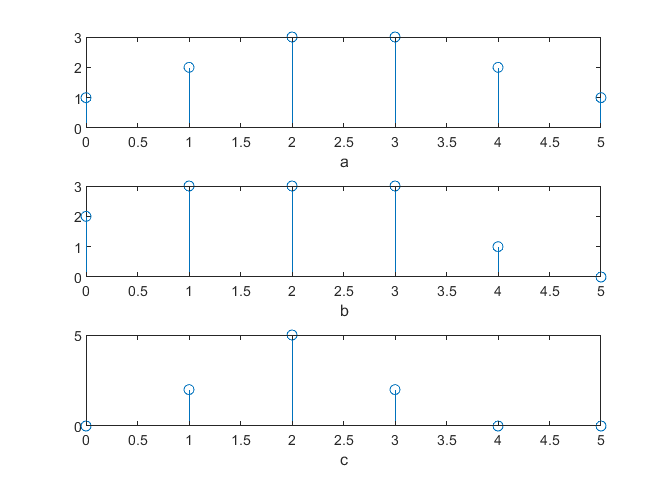

clear 
f = SimpleFunctions;
t = 0:5;

%x[n] and v[n] functions in a,b,c
x1 = f.unitstep(t) - f.unitstep(t-3);
x2 = 2.*f.unitstep(t) - f.unitstep(t-1) - f.unitstep(t-2);
x3 = 2.*f.unitstep(t) - f.unitstep(t-1) - f.unitstep(t-2);

v1 = f.unitstep(t) - f.unitstep(t-4);
v2 = f.unitstep(t) - f.unitstep(t-4);
v3 = f.unitstep(t-1) + f.unitstep(t-2) - 2.*f.unitstep(t-3);

%convs of x[n] and v[n] 
y1 = conv(x1, v1);
y2 = conv(x2, v2);
y3 = conv(x3, v3);

%plot of convs
subplot(3, 1, 1)
stem(t, y1(1:length(t)))
xlabel("a")
subplot(3, 1, 2)
stem(t, y2(1:length(t)))
xlabel("b")
subplot(3, 1, 3)
stem(t, y3(1:length(t)))
xlabel("c")
exportgraphics(gcf, '3tp3_lab2_1b.jpg');

## Part 3

clear
[signal, Fs] = audioread('3TP3_lab2_original.wav');
L = length(signal); % Number of samples in the signal.
T = 1/Fs; % Sampling period in seconds.
t = [0:L-1]*T; % Time vector in seconds.

## Part 4

Te = 0.75; %echo delay in sec
alpha = 0.3; %amplitude/strength of echo
Ldelay = Te*Fs; %delay

%creating echo
signalplusecho = zeros(size(signal));  
signalplusecho(1:Ldelay) = signal(1:Ldelay);  
for i=Ldelay+1:length(signal)  
  signalplusecho(i) = signal(i) + alpha*signal(i-Ldelay);  
end  

%output
signalplusecho = signalplusecho/max(abs(signalplusecho));
audiowrite('3TP3_lab2_part4_echo.wav', signalplusecho, Fs);

## Part 5

clear
[signal, Fs] = audioread('3TP3_lab2_original.wav');
L = length(signal); % Number of samples in the signal.
T = 1/Fs; % Sampling period in seconds.
t = [0:L-1]*T; % Time vector in seconds.
Te = 0.75; %echo delay in sec
alpha = 0.3; %amplitude/strength of echo
Ldelay = Te*Fs; %delay
IR = zeros(Ldelay+1, 1); %create an empty impulse response to generate numbers within it

%Setting the number for the impulse sensor
IR(1) = 1; 
IR(Ldelay+1) = alpha;

signalpulse_conv = conv(signal, IR); %Convolution signal is updated
signalpulse_conv = signalpulse_conv/max(abs(signalpulse_conv));

%Output
audiowrite('3TP3_lab2_part5_echo.wav', signalpulse_conv, Fs);

## Part 7

clear
[signal, Fs] = audioread('3TP3_lab2_original.wav');
L = length(signal); % Number of samples in the signal.
T = 1/Fs; % Sampling period in seconds.
t = [0:L-1]*T; % Time vector in seconds.

Te = 0.75; %echo delay in sec
alpha = 0.3; %amplitude/strength of echo
Ldelay = Te*Fs; %delay
Echonum = 2; %Represent the number of echos

IR = zeros(Echonum*Ldelay+1,1);%create an empty impulse response to generate numbers within it

IR(1) = 1;%IR Number set

%Multiply by number of echos added with the echo strength 
for x = 1:Echonum 
    IR(x*Ldelay +1) = IR(x*Ldelay +1) + alpha^x;
end

%Signal Updated
signalpulse_reverb = conv(signal,IR);
signalpulse_reverb = signalpulse_reverb/max(abs(signalpulse_reverb));

%output
audiowrite('3TP3_lab2_part7_echo.wav', signalpulse_reverb, Fs);